# Práctica No. 3

addpath("src");
import cuantizacionVectorial.*

## Generar puntos

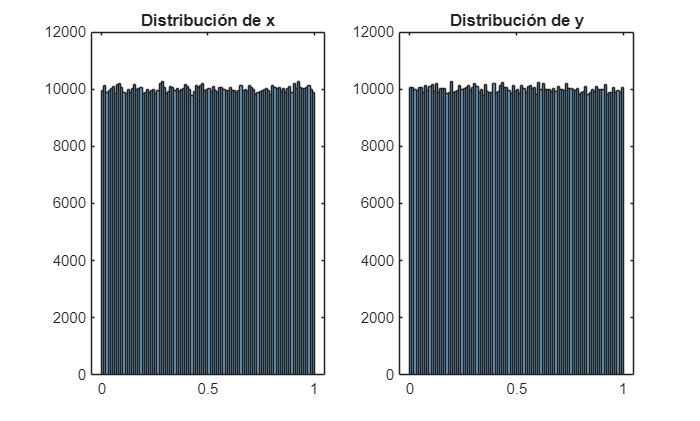

%Definir método y semilla para reproducibilidad.
rng(256,"twister");
%rand da una matriz del tamaño especificado con números al azar
%uniformemente distribuidos en el intervalo (0,1).
%x = columna 1, y = columna 2.
point = rand(1000000,2);

figure(1);
subplot(1,2,1);
histogram(point(:,1));
title("Distribución de x")
subplot(1,2,2);
histogram(point(:,2));
title("Distribución de y")

Las distribuciones individuales se ven uniformes, y no cambian al re-ejecutar la celda.

## Calculamos los cuantizadores para el número de regiones regiones solicitadas por los 3 métodos.

k = [1,2,4,8,16,64,256];
%LBG Fijo
load resultados\cuantizadorLBGFijo.mat
for i = 1:length(k)
    f = @() cuantizacionVectorial.LBG(point,k(i),.0001,1000,"euclideana",[0 .0001]);
    g = @() cuantizacionVectorial.LBG(point,k(i),.0001,1000,"itakura-saito",[0 .0001]);
    [cuantizadorLBG{i,1}, cuantizadorLBG{i,3}] = f();
    %[cuantizadorLBG{i,2}, cuantizadorLBG{i,4}] = g();
    cuantizadorLBG{i,5} = timeit(f);
    %cuantizadorLBG{i,6} = timeit(g); 
    disp(k(i));
end

     1

     2

     4

     8

    16

    64

   256



save resultados\cuantizadorLBGFijo.mat cuantizadorLBG

load resultados\cuantizadorLBGRandom.mat
%LBGRandom
for i = 1:length(k)
    f = @() cuantizacionVectorial.LBG(point,k(i),.0001,1000,"euclideana",[]);
    g = @() cuantizacionVectorial.LBG(point,k(i),.0001,1000,"itakura-saito",[]);
    [cuantizadorLBGRandom{i,1}, cuantizadorLBGRandom{i,3}] = f();
    %[cuantizadorLBGRandom{i,2}, cuantizadorLBGRandom{i,4}] = g();
    cuantizadorLBGRandom{i,5} = timeit(f);
    %cuantizadorLBGRandom{i,6} = timeit(g); 
    disp(k(i));
end

     1

     2

     4

     8

    16

    64

   256



save resultados\cuantizadorLBGRandom.mat cuantizadorLBGRandom

%KMeans naive
load resultados\cuantizadorKMeans.mat
for i = 1:length(k)
    f = @() cuantizacionVectorial.KMedias(point,k(i),.0001,1000,"euclideana",false);
    %g = @() cuantizacionVectorial.KMedias(point,k(i),.0001,1000,"itakura-saito",false);
    [cuantizadorKMeans{i,1}, cuantizadorKMeans{i,3}] = f();
    %[cuantizadorKMeans{i,2}, cuantizadorKMeans{i,4}] = g();
    cuantizadorKMeans{i,5} = timeit(f);
    %cuantizadorKMeans{i,6} = timeit(g); 
    disp(k(i));
end

     1

     2

     4

     8

    16

    64

   256



save resultados\cuantizadorKMeans.mat cuantizadorKMeans

%KMeans++
load resultados\cuantizadorKMeansMasMas.mat
for i = 1:length(k)
    f = @() cuantizacionVectorial.KMedias(point,k(i),.0001,1000,"euclideana",true);
    %g = @() cuantizacionVectorial.KMedias(point,k(i),.0001,1000,"itakura-saito",true);
    [cuantizadorKMeansMasMas{i,1}, cuantizadorKMeansMasMas{i,3}] = f();
    %[cuantizadorKMeansMasMas{i,2}, cuantizadorKMeansMasMas{i,4}] = g();
    cuantizadorKMeansMasMas{i,5} = timeit(f);
    %cuantizadorKMeansMasMas{i,6} = timeit(g); 
    disp(k(i));
end

     1

     2

     4

     8

    16

    64

   256



save resultados\cuantizadorKMeansMasMas.mat cuantizadorKMeansMasMas

## Comparar con resultados teóricos

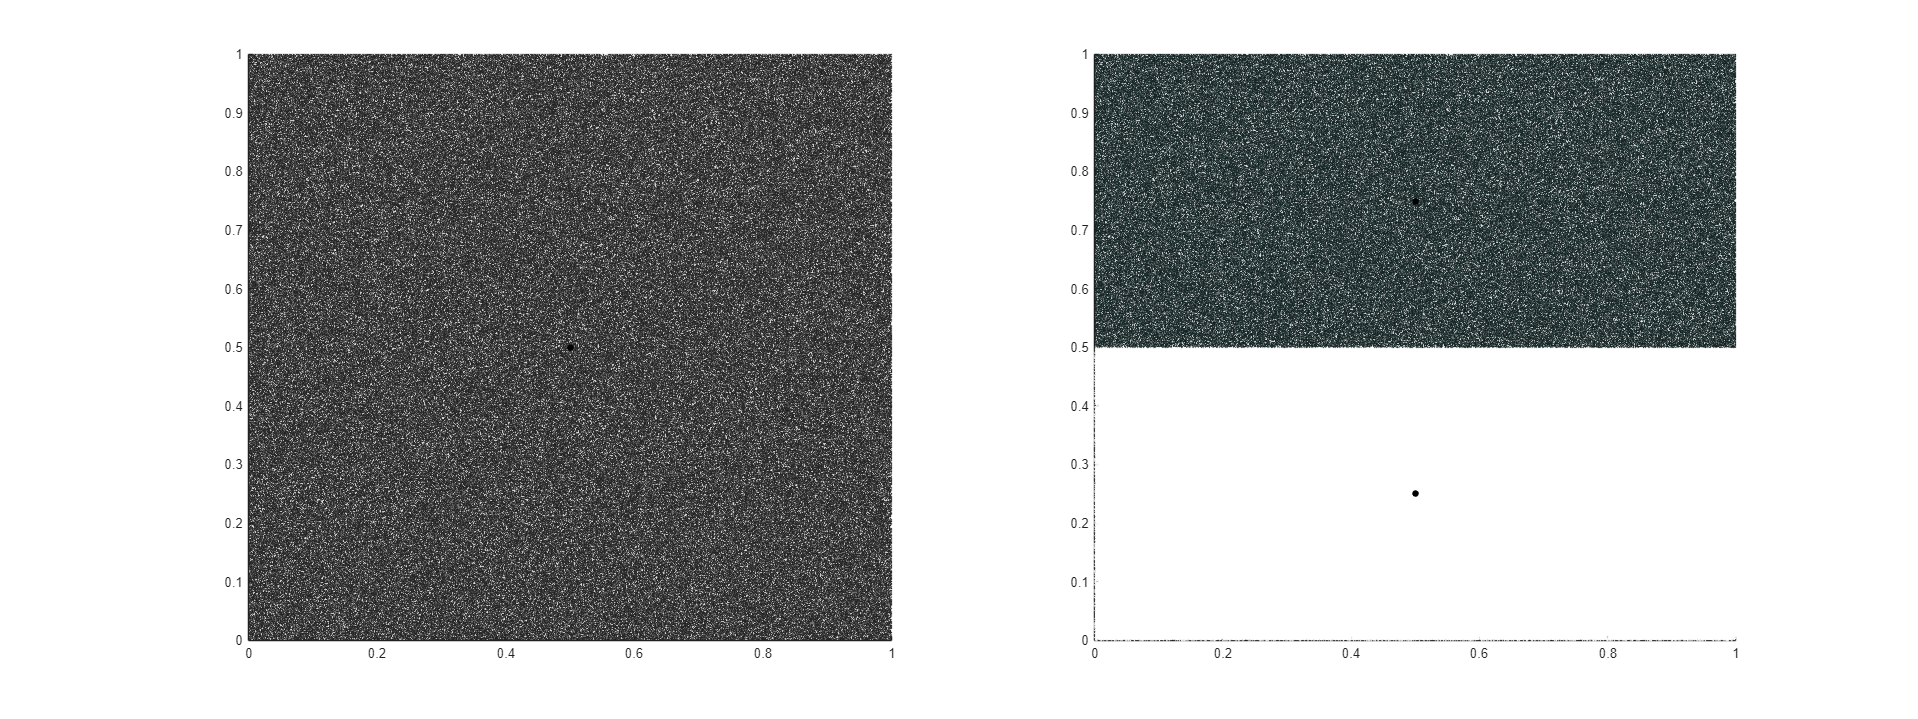

load resultados\cuantizadorLBGFijo.mat
load resultados\cuantizadorLBGRandom.mat
load resultados\cuantizadorKMeans.mat
load resultados\cuantizadorKMeansMasMas.mat
figure('Position',[0 0 2000 750]);
subplot(1,2,1);
cuantizacionVectorial.grafRegiones(point,cuantizadorLBG{1,1},"euclideana");
subplot(1,2,2)
cuantizacionVectorial.grafRegiones(point,cuantizadorLBG{2,1},"euclideana");

Las regiones para k=1,2 de LBG con perturbación fija son muy parecidas a las teóricas.

## Comparar todos los métodos

Distancias globales de los métodos con distancias euclideanas

%Distancias globales euclid
table(cuantizadorLBG(:,3),cuantizadorLBGRandom(:,3),cuantizadorKMeans(:,3),cuantizadorKMeansMasMas(:,3), ...
    'VariableNames', ["LBG fijo" "LBG aleatoria" "K-medias" "K-medias++"],'rowNames', ["1","2","4","8","16","64","256"],'DimensionNames',["k" "Método"])

ans = 7×4 table
              LBG fijo       LBG aleatoria        K-medias         K-medias++  
           ______________    ______________    ______________    ______________

    1      {[1.6665e+05]}    {[1.6665e+05]}    {[1.6665e+05]}    {[1.6665e+05]}
    2      {[1.0422e+05]}    {[1.0413e+05]}    {[1.0413e+05]}    {[1.0413e+05]}
    4      {[4.1695e+04]}    {[4.1696e+04]}    {[4.1695e+04]}    {[4.1696e+04]}
    8      {[2.6070e+04]}    {[2.1369e+04]}    {[2.1652e+04]}    {[2.1668e+04]}
    16     {[1.0394e+04]}    {[1.0398e+04]}    {[1.0697e+04]}    {[1.0411e+04]}
    64     {[2.5907e+03]}    {[2.5904e+03]}    {[2.5804e+03]}    {[2.5928e+03]}
    256    {[  641.4097]}    {[  639.0931]}    {[  644.3852]}    {[  641.0879]}


Tiempo de ejecución de los métodos con distancias euclideana

%Tiempo de ejecución (s) euclid
table(cuantizadorLBG(:,5),cuantizadorLBGRandom(:,5),cuantizadorKMeans(:,5),cuantizadorKMeansMasMas(:,5), ...
    'VariableNames', ["LBG fijo" "LBG aleatoria" "K-medias" "K-medias++"],'rowNames', ["1","2","4","8","16","64","256"],'DimensionNames',["k" "Método"])

ans = 7×4 table
             LBG fijo      LBG aleatoria     K-medias       K-medias++ 
           ____________    _____________    ___________    ____________

    1      {[  0.0172]}    {[  0.0206]}     {[ 0.2994]}    {[  0.1632]}
    2      {[  0.0880]}    {[  0.5862]}     {[ 0.9917]}    {[  0.5362]}
    4      {[  0.8361]}    {[  1.3707]}     {[ 0.9973]}    {[  1.0996]}
    8      {[  1.4178]}    {[  3.9445]}     {[ 3.0518]}    {[  3.1310]}
    16     {[  4.0357]}    {[ 13.3154]}     {[ 5.2358]}    {[  9.5807]}
    64     {[ 43.0055]}    {[ 45.3047]}     {[22.0744]}    {[ 36.4586]}
    256    {[159.1364]}    {[219.1906]}     {[84.0373]}    {[308.8303]}


Distancias globales de los métodos con distancia de Itakura-saito

%Distancias globales 
table(cuantizadorLBG(:,4),cuantizadorLBGRandom(:,4),cuantizadorKMeans(:,4),cuantizadorKMeansMasMas(:,4), ...
    'VariableNames', ["LBG fijo" "LBG aleatoria" "K-medias" "K-medias++"],'rowNames', ["1","2","4","8","16","64","256"],'DimensionNames',["k" "Método"])

ans = 7×4 table
             LBG fijo      LBG aleatoria      K-medias       K-medias++ 
           ____________    _____________    ____________    ____________

    1      {0×0 double}    {0×0 double}     {0×0 double}    {0×0 double}
    2      {0×0 double}    {0×0 double}     {0×0 double}    {0×0 double}
    4      {0×0 double}    {0×0 double}     {0×0 double}    {0×0 double}
    8      {0×0 double}    {0×0 double}     {0×0 double}    {0×0 double}
    16     {0×0 double}    {0×0 double}     {0×0 double}    {0×0 double}
    64     {0×0 double}    {0×0 double}     {0×0 double}    {0×0 double}
    256    {0×0 double}    {0×0 double}     {0×0 double}    {0×0 double}


Tiempo de ejecución de los métodos con distancia de Itakura-saito

%Distancias globales 
table(cuantizadorLBG(:,6),cuantizadorLBGRandom(:,6),cuantizadorKMeans(:,6),cuantizadorKMeansMasMas(:,6), ...
    'VariableNames', ["LBG fijo" "LBG aleatoria" "K-medias" "K-medias++"],'rowNames', ["1","2","4","8","16","64","256"],'DimensionNames',["k" "Método"])

ans = 7×4 table
             LBG fijo      LBG aleatoria      K-medias       K-medias++ 
           ____________    _____________    ____________    ____________

    1      {0×0 double}    {0×0 double}     {0×0 double}    {0×0 double}
    2      {0×0 double}    {0×0 double}     {0×0 double}    {0×0 double}
    4      {0×0 double}    {0×0 double}     {0×0 double}    {0×0 double}
    8      {0×0 double}    {0×0 double}     {0×0 double}    {0×0 double}
    16     {0×0 double}    {0×0 double}     {0×0 double}    {0×0 double}
    64     {0×0 double}    {0×0 double}     {0×0 double}    {0×0 double}
    256    {0×0 double}    {0×0 double}     {0×0 double}    {0×0 double}


Gráfica de regiones de los métodos dado el número de regiones.

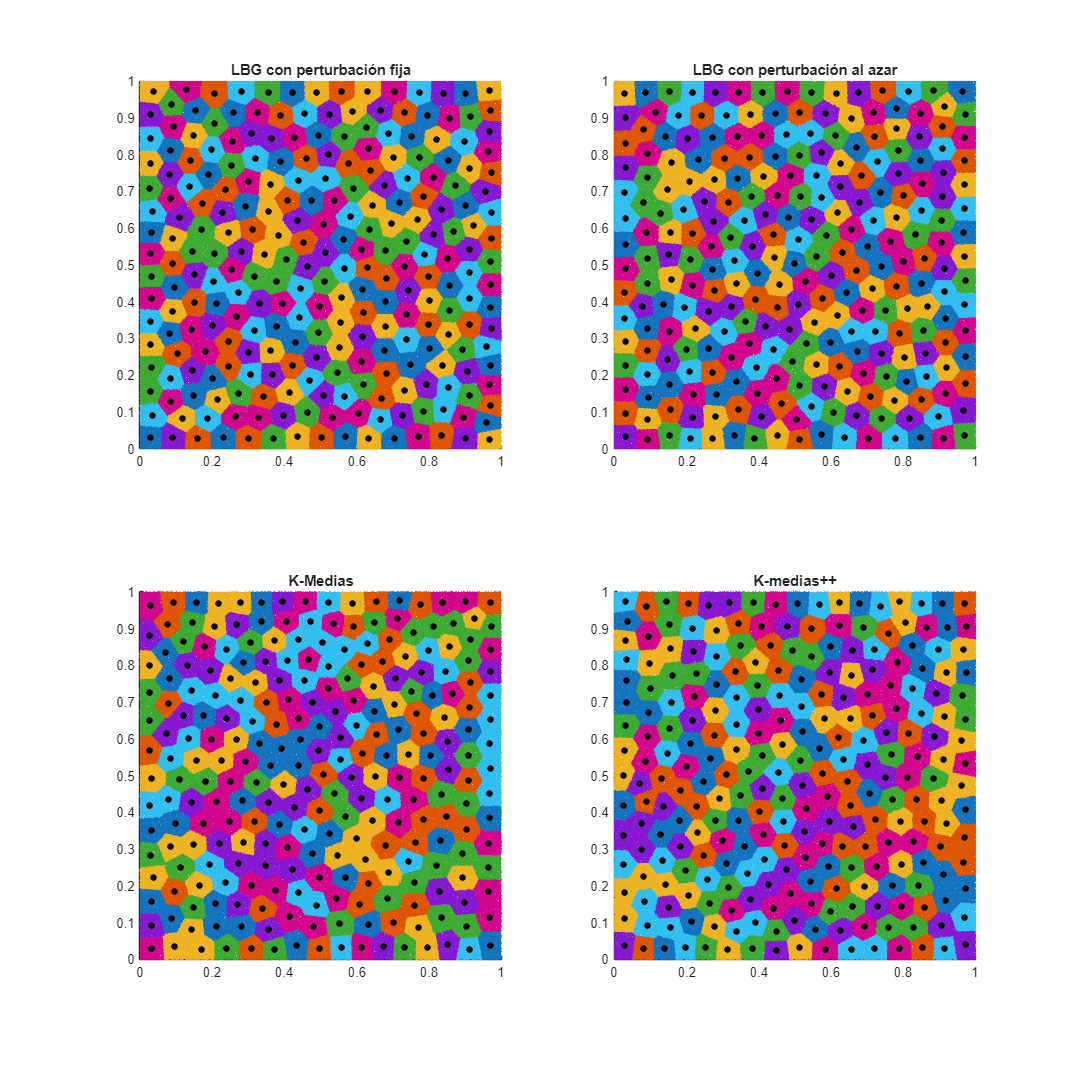

k = 7;
figure('Position',[0 0 1500 1500]);
subplot(2,2,1)
cuantizacionVectorial.grafRegiones(point,cell2mat(cuantizadorLBG(k,1)),"euclideana");
title("LBG con perturbación fija")
subplot(2,2,2)
cuantizacionVectorial.grafRegiones(point,cell2mat(cuantizadorLBGRandom(k,1)),"euclideana");
title("LBG con perturbación al azar")
subplot(2,2,3)
cuantizacionVectorial.grafRegiones(point,cell2mat(cuantizadorKMeans(k,1)),"euclideana");
title("K-Medias")
subplot(2,2,4)
cuantizacionVectorial.grafRegiones(point,cell2mat(cuantizadorKMeansMasMas(k,1)),"euclideana");
title("K-medias++")

## Sistema de reconocimiento de voz

addpath("src");
import reconocimento.*

entrenamiento = dir('.\voz_grabaciones\entrenamiento\*.wav');
X = cell(length(entrenamiento),1);
Y = zeros(length(entrenamiento),1);
for i = 1:length(entrenamiento)
    X{i} = audioread(entrenamiento(i).folder + "\" + entrenamiento(i).name);
    clase = entrenamiento(i).name(8:9);
    if clase(end) == "_"
        clase = clase(1);
    end
    Y(i,:) = str2double(clase);
end

rec = reconocimiento(160, 64, .0001, .000008, 12, "LBGAleatorio",16,.001,1000);
rec = rec.entrenamiento(X,Y);

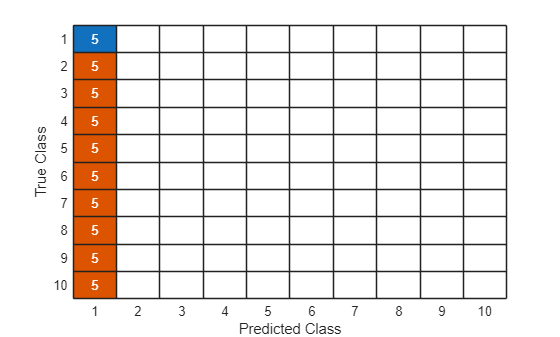

[pred, trueLabel] = rec.inferencia(".\voz_grabaciones\prueba");
cm = confusionmat(trueLabel, pred);
figure();
confusionchart(cm);

addpath("src");
import cuantizacionVectorial.*
cuantizacionVectorial.LBG(point,4,.001,1000,"itakura-saito",[])